The voltage of a capacitor is given as V(t)

syms t x
V(t) = piecewise(0<t&t<1,50*t,1<t&t<3,100-50*t,3<t&t<4,-200+50*t,0)

$$V(t) = \left\{ \begin{array}{cl} 50\,t & \text{ if }t\in \left(0,1\right)\\ 100-50\,t & \text{ if }t\in \left(1,3\right)\\ 50\,t-200 & \text{ if }t\in \left(3,4\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

The waveform of V(t)

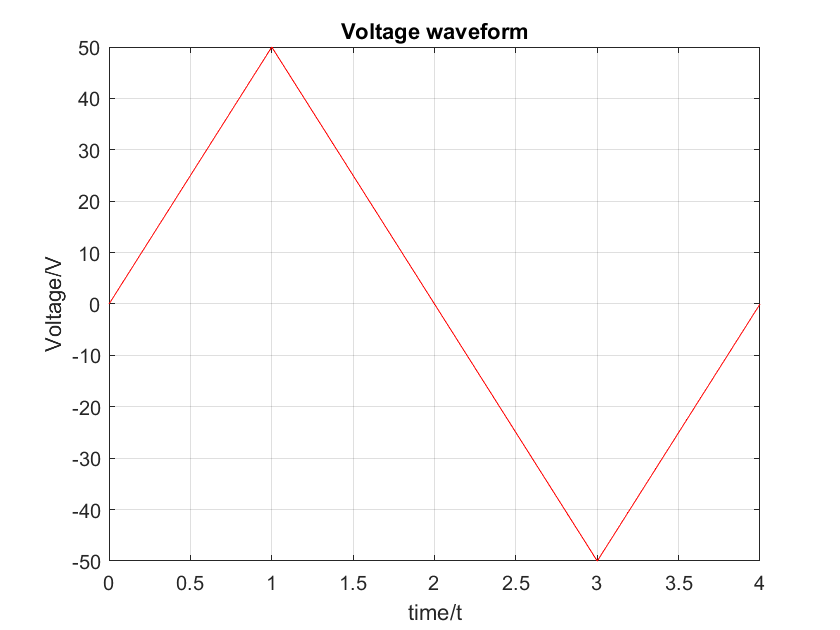

fplot(V(t),[0 4],'r')
title("Voltage waveform")
xlabel("time/t"); ylabel("Voltage/V"); grid on

Expression for the capacitance C(t)

C = 200e-6

C = 2.0000e-04

i = C*diff(V(t),t)

$$i = \left\{ \begin{array}{cl} \frac{1}{100} & \text{ if }t\in \left(0,1\right)\\ -\frac{1}{100} & \text{ if }t\in \left(1,3\right)\\ \frac{1}{100} & \text{ if }t\in \left(3,4\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

The waveform of C(t)

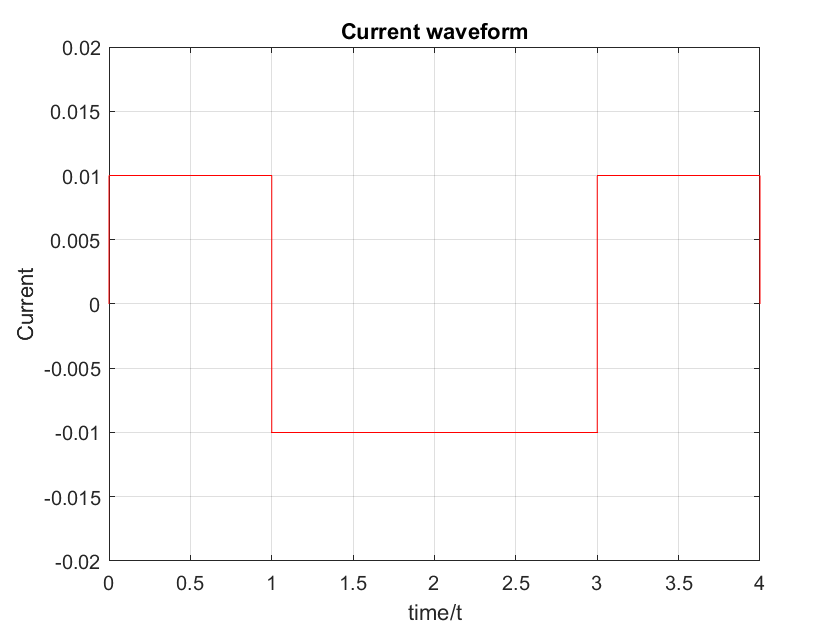

fplot(i,[0 4],'r')
title("Current waveform")
xlabel("time/t"); ylabel("Current")
ylim([-0.02 0.02]); grid on

The charge Q(t)

q(t) = 6*t*cos(5*pi*t)

$$q(t) = 6\,t\,\cos\left(5\,\pi \,t\right)$$

The computed current

current = diff(q(t),t)

$$current = 6\,\cos\left(5\,\pi \,t\right)-30\,\pi \,t\,\sin\left(5\,\pi \,t\right)$$